% %% Part 2.1: Capture Audio
% clear all
% close all
% % @params add line
% devinfo = audiodevinfo;
% speaker = devinfo.output(1).ID;
% mic = devinfo.input(2).ID;
% Fs = 8000;
% bits = 16;
% channels = 1;
% recordTime = 10;
% 
% % Recorder Object
% recorder = audiorecorder(Fs, bits, channels, mic);
% disp('Record begin');
% recordblocking(recorder, recordTime);
% disp('Record finish');
% audio = getaudiodata(recorder);
% % plot([1:length(audio)]/Fs,audio), xlabel('time (s)'), ylabel('Amplitude');
% % play(recorder);
% 
% % Save Audio Clip
% save('audioclip.mat','audio','Fs','bits','channels', 'recordTime', '-append');


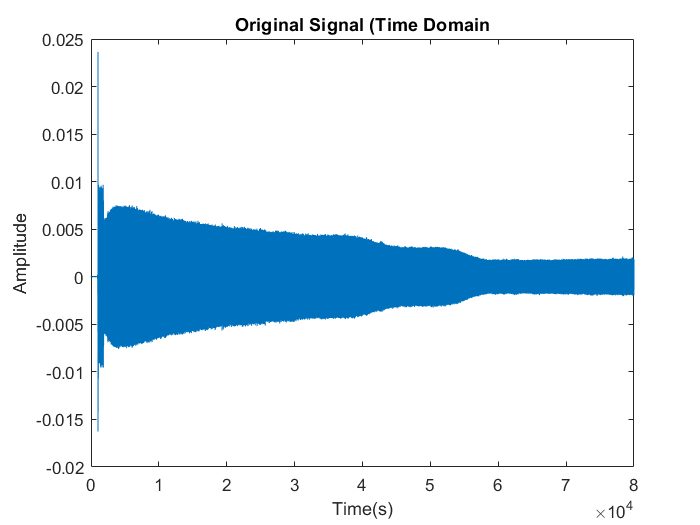


%% Part 2.2: Analyze Audio a
clear all
load audioclip.mat;
N = 8000;

X_f = fft(audio, N)/N;
F = -Fs/2:Fs/N:(N-1)*Fs/(2*N);
X_f_db = 10*log(abs(X_f));
X_omg = fftshift(X_f_db);

figure
plot(audio)
title('Original Signal (Time Domain')
xlabel('Time(s)')
ylabel('Amplitude')

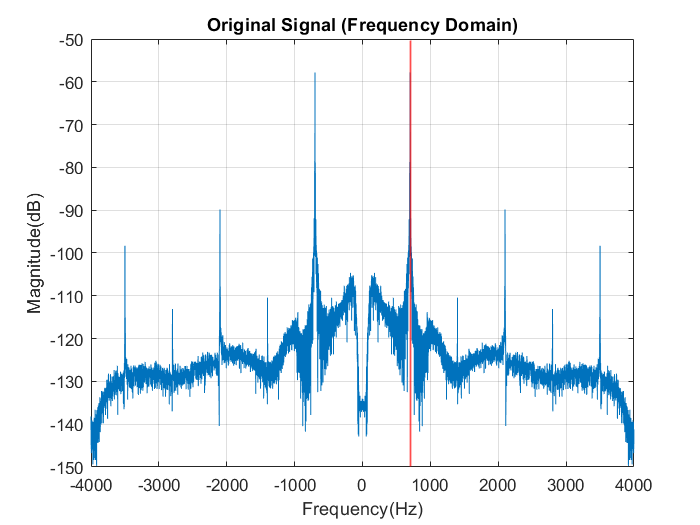


figure 
plot(F, X_omg)
title('Original Signal (Frequency Domain)')
xlabel('Frequency(Hz)')
ylabel('Magnitude(dB)')
xline(700, 'linewidth', 1, 'color', 'r');
grid on

%PLAY ORIGINAL SOUND
sound(audio)

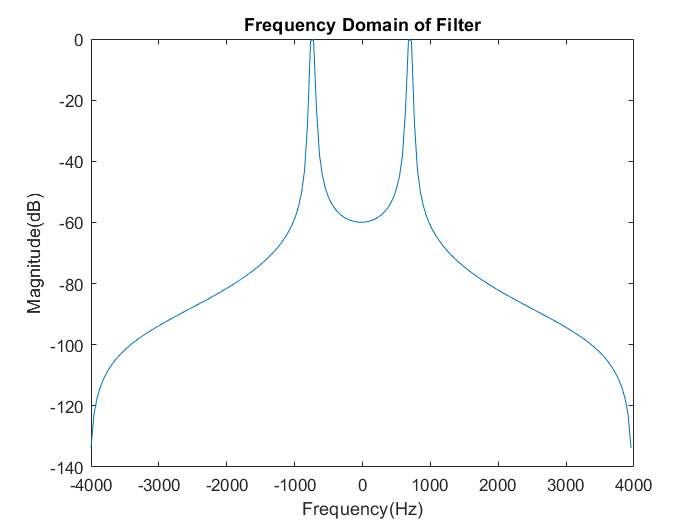


%% Part 4.1: Noise Signal 

N = 5000;
Fs = 8000;
load audioclip.mat;
noise = audio + 0.01*randn(length(audio),1);
Xf_noise = fft(noise, N)/N;

X_f_noisy = fft(audio, N)/N;
F = -Fs/2:Fs/N:(N-1)*Fs/(2*N);
%plot(F,fftshift((abs(X_f_noisy))))

% filteredSignal = filter(Hd, noise); %%filter is called by Hd
% filteredSignalTransform = fft(filteredSignal, N)/N;

% Filter Design
Fc1=675; % Inner cutoff freq.
Fc2=765; % Outter cutoff freq.
L=91; % number of coefficients
n=0:2*L;
h_LPF_1=2*Fc1/Fs*sinc(2*Fc1/Fs*(n-L)); % Shorter LPF
h_LPF_2=2*Fc2/Fs*sinc(2*Fc2/Fs*(n-L)); % Longer LPF
h_LPF = h_LPF_2 - h_LPF_1; % Bandpass = Longer LPF - Shorter LPF
h_LPF_attenuated = h_LPF * 4; % attenuated bandpass
H_LPF = fft(h_LPF);
F_filter = -Fs/2:Fs/length(H_LPF):(length(H_LPF)-1)*Fs/(2*length(H_LPF));
% plot(F_filter, fftshift(abs(H_LPF))); % frequency magnitude plot of the
% filter

% Filter plot in Frequency Domain
figure
plot(F_filter, fftshift(10*log(abs(H_LPF))));
title('Frequency Domain of Filter')
xlabel('Frequency(Hz)')
ylabel('Magnitude(dB)')

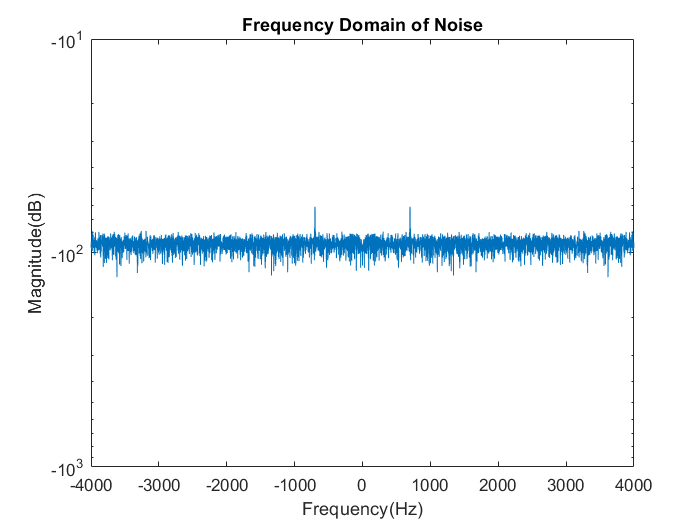


% Filtered Signal
filteredSignal = conv(h_LPF_attenuated, noise);
filteredSignalTransform = fft(filteredSignal, N)/N;

% Plot of the noisy signal in frequency domain
figure
semilogy(F, fftshift(10*log(abs(Xf_noise))))
title('Frequency Domain of Noise')
xlabel('Frequency(Hz)')
ylabel('Magnitude(dB)')

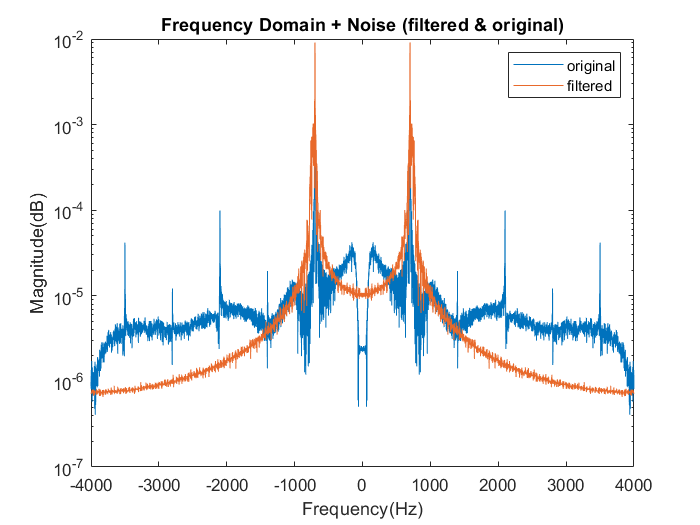


% Plot of original audio and filtered signal in freq. domain
figure(4)
semilogy(F, fftshift(abs(X_f_noisy)))
title('Frequency Domain + Noise (filtered & original)')
xlabel('Frequency(Hz)')
ylabel('Magnitude(dB)')

hold on
semilogy(F, fftshift(abs(filteredSignalTransform)),"Color", [0.9100    0.4100    0.1700])
legend('original', 'filtered')


% % Plot of noise and filtered signal in time domain
% figure(2)
% plot(noise)
% title('Noisy signal + Filtered signal (Time Domain)')
% xlabel('Time(s)')
% ylabel('Amplitude')
% hold on
% plot(filteredSignal,"Color",[0.9100    0.4100    0.1700] )
% legend('Noise', 'filtered')
% hold off

% Computing signal to noise ratio
signal_to_noise_ratio = snr(filteredSignal)

signal_to_noise_ratio = 5.0096

%PLAY NOISY SOUND
sound(noise)

%PLAY FILTERED SOUND
sound(filteredSignal)

% Can use to plot the audio
% figure
% plot(output_audio)
% hold on
% plot(audio), title('Time plot of the filtered signal and original')

% filterDesigner


% sound(audio)